
clc,clear,close all
c = 3e8;                         %光速 
Tr = 100e-6;                    %脉冲重复周期
totalR=c*Tr/2

totalR = 15000

f0 = 10e9;                      %载频
Tp = 10e-6;                      %脉冲宽度
B = 10e6;                         %带宽
u = B/Tp;                        %调频率
fs = 4*B;                        %采样率
N = 64;                          %脉冲数
t = 1/fs:1/fs:Tr;               %回波信号时间序列
SampleNumber=fix(fs*Tr)         %一个脉冲周期的采样点数；

SampleNumber = 4000

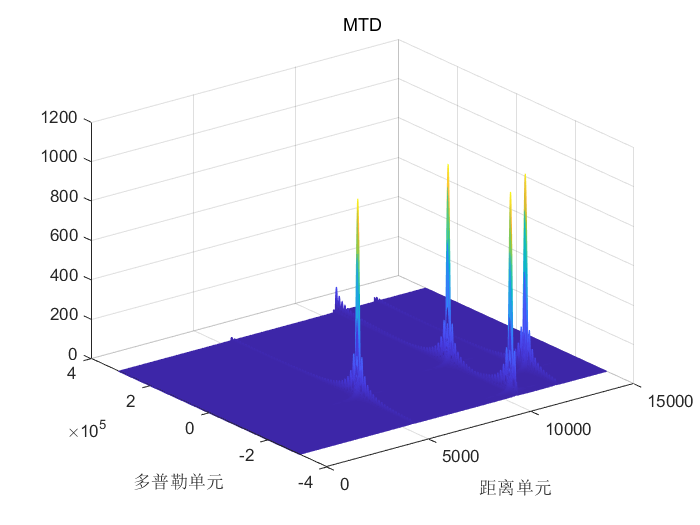

targetNumber=4;                            %目标个数
R0 = [3e3,3.1e3,5e3,13e3];                  %目标距离
v = [20,70,50,30];                           %径向速度
pnum = 4;                                  %保护单元
rnum = 10;                                 %参考单元
pfa = 1e-6;                                %恒虚警率
M_scale=32;                                %MTD的多普勒门
r_range=(0:length(t)-1)*totalR/(length(t)-1);
v_range = (-N/2:N/2-1)*c/2/f0/N/Tr;

load("signal_imag_out.txt");
load("signal_real_out.txt");
signal=signal_real_out-1i*signal_imag_out;
signal=reshape(signal,[64,4000])';      %nmd'是转置+取共轭, 草泥马的
%mesh(r_range,v_range,abs(signal))
pc=signal;


% %%=================脉冲压缩===================%% 
% tt=0:1/fs:Tr-1/fs;
% ttt=0:1/fs:Tp-1/fs;
% ori=[exp(j*pi*u*ttt.^2).*exp(-j*2*pi*f0*ttt), zeros(1,length(tt)-length(ttt))];        %我不是很理解
% signal_fft=fft(signal,[],2);
% ori_fft=fft(ori);
% shit=signal_fft.*conj(ori_fft);
% pc=ifft(shit,[],2);
% plot(tt,abs(pc(1,:)))
% 
% title('脉冲压缩')
% xlabel('距离单元')
% 
% r_range=(0:length(t)-1)*totalR/(length(t)-1);
% v_range = (-N/2:N/2-1)*c/2/f0/N/Tr;
% mesh(r_range,v_range,(abs(pc)))
% plot(1:4000, abs(fft(abs(pc(1,:)),4000)))
%%=================MTD===================%% 
% mtd=fft(pc);
% [m,n]=size(mtd);
% mtd=fftshift(mtd);
%mesh(1:n,1:m,abs(fftshift(mtd)))
r_range=(0:length(t)-1)*totalR/(length(t)-1);
v_range = (-M_scale*N/2:M_scale*N/2-1)*c/2/f0/M_scale*N/Tr;

mtd=fft(pc,M_scale*N,2);   %通常K>M
mtd=conj(mtd)';
mtd=fftshift(mtd);
mesh(r_range,v_range,abs(mtd))
title('MTD')
xlabel('距离单元')
ylabel('多普勒单元')

%%=================CA-CFAR===================%% 
% pnum = 4;                                  %保护单元
% rnum = 10;                                 %参考单元
% pfa = 1e-6;                                %恒虚警率
% Kk = pfa^(-1/(2*rnum))-1                %门限系数
% cfar=zeros(N,SampleNumber);
% mtd2=abs(mtd).^2;
% for i=1:M_scale*N
%     sss=mtd2(i,:);
%     for ii=pnum+rnum+1:SampleNumber-pnum-rnum                   
%         sIndex=[ii-pnum+rnum:ii-pnum-1 ii+pnum+1:ii+rnum+pnum];
%         aaa(ii)=sum(sss(sIndex))/(2*rnum);
%         %aaa=(pc2(i,j-5)+pc2(i,j-4)+pc2(i,j-3)+pc2(i,j-2)+pc2(i,j+2)+pc2(i,j+3)+pc2(i,j+4)+pc2(i,j+5))/8.0;
%         thold(ii)=Kk*aaa(ii);
%         if  (mtd2(i,ii)>thold(ii))%&&(mtd2(i,ii)>20)
%             cfar(i,ii)=mtd2(i,ii);
%         else
%             cfar(i,ii)=0;
%         end
%     end
%     if(i==4)
%         plot(1:length(thold),10*log10(thold))
%         hold on
%         plot(1:length(mtd(i,:)),10*log10(mtd2(i,:)))
%         hold off
%         legend({'门限','快时间'})
%         title('CA-CFAR')
%     end
% end
% [m,n]=size(cfar);
% mesh(r_range,v_range,(cfar)/3200);
% title('CA-CFAR')
% xlabel('距离单元')
% ylabel('多普勒单元')


